clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.5);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1016

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.1250

one = 0

two = 0

three = -0.2500

one = 0

two = 0

three = -0.8750

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -1

one = 0

two = 0.0138

three = -0.0703

one = 0

two = 0.0138

three = 0.5001

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 1

one = 0

two = 0.0138

three = 0.8730

one = -0.0078

two = 0.0138

three = -0.1172

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = 0.0138

three = -0.0859

one = 0

two = -0.0742

three = 0

one = 0.0374

two = -0.4531

three = 0

one = 0.1315

two = -0.9453

three = 0

one = 0.1432

two = -1

three = 0

one = 0.1432

two = -1

three = 0

one = 0.1550

two = -1

three = 0

one = 0.1315

two = -1

three = -0.1641

one = 0.0648

two = -0.9531

three = -0.8750

one = -0.1094

two = -0.9727

three = -1

one = -0.1875

two = -0.9609

three = -1

one = -0.4062

two = -0.8672

three = -0.6719

one = -0.6875

two = -0.7656

three = -0.3359

one = -0.9727

two = -0.7656

three = -0.2891

one = -1

two = -0.7656

three = -0.2266

one = -1

two = -0.7656

three = -0.2266

one = -0.6992

two = -0.8281

three = -0.2578

one = -0.1035

two = -0.8672

three = -0.3203

one = 0.5706

two = -0.8437

three = -0.2891

one = 1

two = -0.7812

three = -0.2109

one = 1

two = -0.7031

three = -0.2109

one = 1

two = -0.6641

three = -0.1953

one = 1

two = -0.6641

three = -0.1797

one = 0.9039

two = -0.7266

three = -0.1797

one = -0.5020

two = -0.7656

three = -0.0078

one = -1

two = -0.7480

three = -0.0078

one = -1

two = -0.7598

three = -0.0391

one = -1

two = -0.7656

three = -0.0547

one = -0.1992

two = -0.7422

three = -0.0391

one = 0.9079

two = -0.5801

three = -0.1797

one = 1

two = -0.5469

three = -0.1328

one = 1

two = -0.5469

three = -0.0859

one = 1

two = -0.5469

three = -0.0859

one = 1

two = -0.5469

three = -0.0859

one = 0.9882

two = -0.5469

three = -0.0859

one = 0.7687

two = -0.4062

three = -0.0859

one = -0.0078

two = 0.0256

three = -0.0547

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0256

three = -0.0859

one = 0

two = 0.0256

three = -0.0859

one = 0

two = 0.0374

three = -0.0859

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0138

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0256

three = -0.0547

one = 0

two = 0.0138

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0374

three = -0.0547

one = 0

two = 0.0197

three = -0.0703

one = 0

two = 0.0315

three = -0.0703

one = 0

two = 0.0138

three = -0.0703

one = 0

two = -0.1035

three = 0

one = 0.1550

two = -0.8691

three = 0

one = 0.3354

two = -1

three = -0.0078

one = 0.3354

two = -1

three = -0.0078

one = 0.3118

two = -1

three = -0.0078

one = 0.2903

two = -1

three = -0.0078

one = 0.1040

two = -0.9336

three = -0.0078

one = -0.0703

two = -0.2305

three = -0.0078

one = -0.0078

two = -0.1016

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

one = -0.0078

two = -0.0859

three = -0.0078

lid = LIDAR('COM4')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(10000);

gps = NEO_M8U_USB('COM7')

gps =   NEO_M8U_USB with properties:

         DEFAULT_NAME: "USB_NEO_M8U"
    DEFAULT_BAUD_RATE: 9600
    DEFAULT_DATA_TYPE: "uint8"
                  ubx: [1×1 UBX]
               device: [1×1 internal.Serialport]
                 data: []
                 plot: []



gps_data = gps.getBasic();

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

msg = 'retrying...'

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')

gpsPoint =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '*'
         MarkerSize: 6
    MarkerFaceColor: 'none'
       LatitudeData: 42.2935
      LongitudeData: -71.2640
              ZData: [1×0 double]

  Show all properties


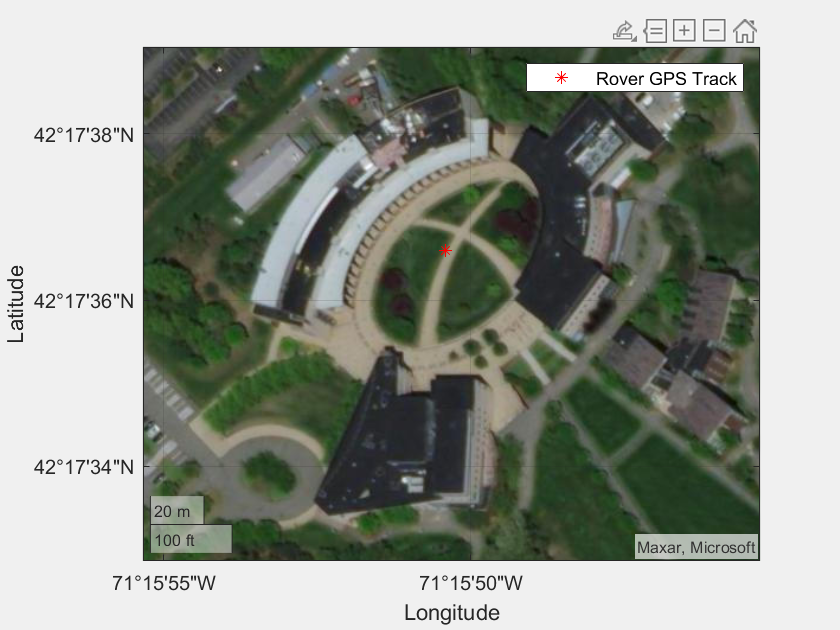

% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')

movegui(gpsRoverPlot,'south');

Unrecognized function or variable 'gpsRoverPlot'.

hold off;

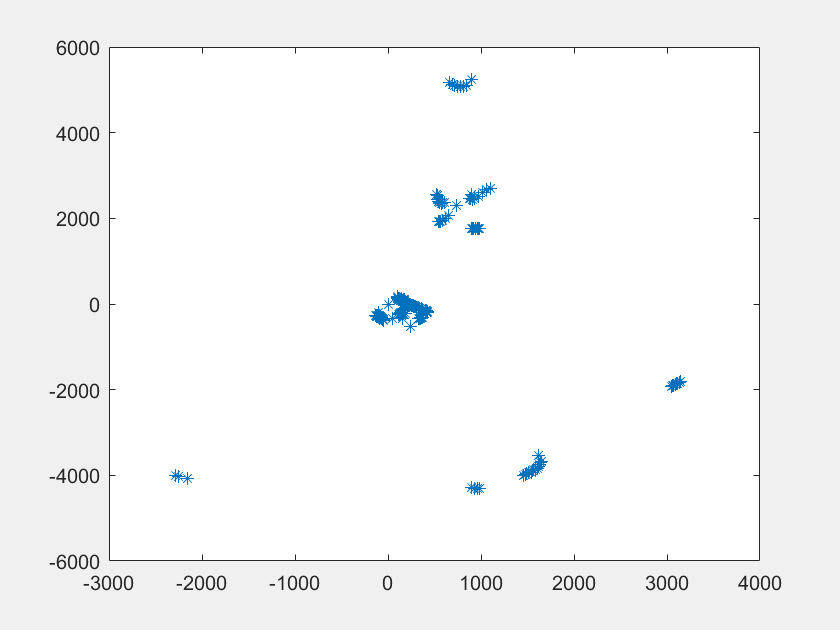

plot(lidar_data(1,:), lidar_data(2,:), '*')

save('4-27-lg-01', ["lidar_data", "gps_data"])

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');


function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function wave, waypoints = gpsWaypoint(gps_data, waypoints)
    [dist, angle] = distance(gps_data.latitude, gps_data.longitude, wlat, wlon);
    if dist < cutoff
        waypoints(0) = [];
    end
    delta = angdiff(gps_data.heading, angle);
    if delta > pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 0 0 1 2]);
    elseif delta > 0
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 1 2 0 0]);
    elseif delta < -pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [2 1 0 0 0 0 0]);
    else
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 2 1 0 0 0]);
    end
end

function wave = lidarWallFollow(lidar_data)
    
end